%% Roshan Jaiswal-Ferri
%Section - 01 
%Aero 355 Midterm: 2/20/25

%% Workspace Prep

format long     %Allows for more accurate decimals
close all;      %Clears all
clear all;      %Clears Workspace
clc;            %Clears Command Window

# Question 4) 

You are deciding on materials for the external  portion of your spacecraft and you are worried about contamination.  The next few questions deal with this problem.

part a) Calculate and plot the residence time for temperatures from  50-300 K at activation energies of 10 and 20 kcal/mole.  Put the lines  on a single plot. Use τ0=3x10-12. Hint: I use semilogx (logs the x axis to be able to see the results better). Use R=1.9858775*10^-3 kcal/K*mole.

## Vars

t0 = 3e-12;
Ea1 = 10; %kcal/mol
Ea2 = 20; %kcal/mol
R = 1.9858775e-3; %kcal/K*mol
K = linspace(50,300,251);

## EQs:

tao1 = t0*exp(Ea1./(R.*K));
tao2 = t0*exp(Ea2./(R.*K));

## Plotting

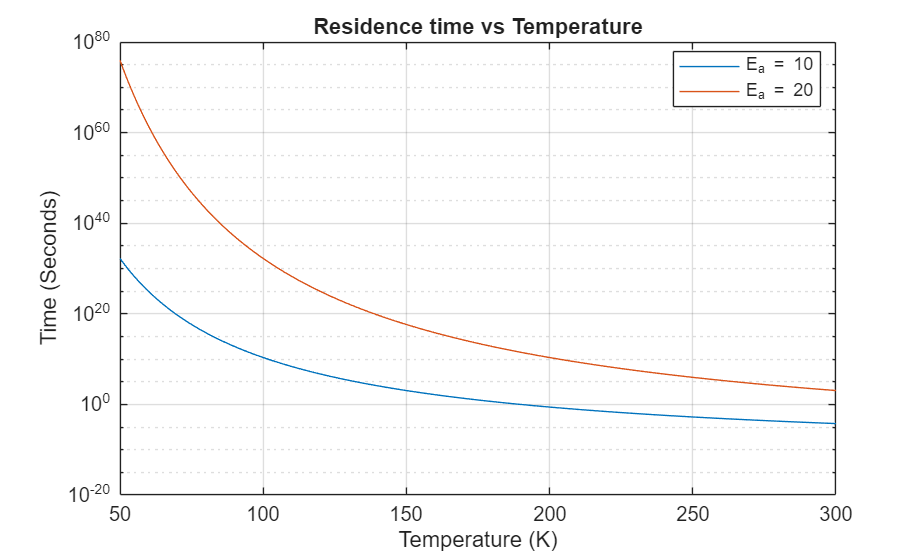

figure('Name','Residence time')
semilogy(K,tao1);
hold on
grid on
semilogy(K,tao2);
ylabel('Time (Seconds)')
xlabel('Temperature (K)')
legend('E_a = 10','E_a = 20', Location='best')
title('Residence time vs Temperature')

# Question 6:

Based on the previous problem results, what is the amount of time in  secs that a contaminate will stay chosen material (from the question  above) at 150 K? Give the answer to the nearest second. 

disp(num2str(t0*exp(Ea1/(R*150))));

1139.0768


# Question 7:

Final Picked a Material but now you need more information

part a) Graphically show the **daily **mass loss for a 5 g for each of the first seven days of the mission for a temperature of 100C using activation energy Ea=15 kcal/mol.  You should have seven points connected with a line.

TML of 0.25% and a CVCM of 0.01% for the material that you are testing

Consider day 1 to be (0-24 hrs) and then each day is 24 hours more.

## Vars

TML = 0.0025;
M1 = 5; %g
dM = TML*M1;
R = 1.9858775e-3; %kcal/K*mol
Ea = 15; %kcal/mol
T = 373.15; %kelvin

## EQs

q0 = (dM/(2*exp(-Ea/(R*T))*(24^(0.5))));
time = linspace(1,7,7); %this is for plotting only
count = 1;
for i = 24:24:168
    t2 = i;
    t1 = i - 24;
    dm(count) = 2*q0*exp(-Ea/(R*T))*((t2^0.5)-(t1^0.5));
    count = count + 1;
end

## Plotting

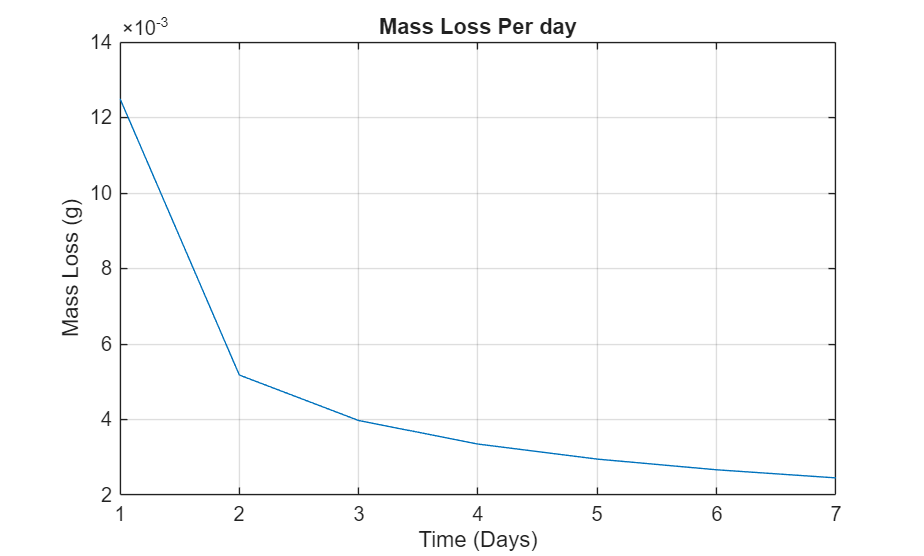

figure('Name','Mass Loss Per day')
plot(time,dm)
grid on
ylabel('Mass Loss (g)')
xlabel('Time (Days)')
title('Mass Loss Per day')

# Question 8)

Still testing

The material chosen has the following properties:

5 g

activation energy Ea=15 kcal/mol

TML of 0.25% and a CVCM of 0.01%

part b) What is the mass loss (g) for day 2 at 100 C? Give results to **four** decimal places

disp(num2str(dm(2)));

0.0051777


# Question 9)

Still testing

Part c) For the same seven day period and same material and temp, calculate  and plot the daily arrival rate vs time for each day for view factors  varying from 0.003 to 0.03 if temperature is 100 C and activation energy is 15 kcal/mol.   Assume the density is 1 g/cm3.

## Vars

VF = linspace(0.003,0.03,10);
T = 373.15; %K
t = time.*24;
rho = 1; %g/cm^3

## EQs

mdot = q0*(exp(-Ea/(R*T))./t.^0.5); %in grams not kilos

for i = 1:1:10
    for j = 1:7
        ra(i,j) = (VF(i)*mdot(j))/rho; %cm^3/s
    end
end

## Plotting

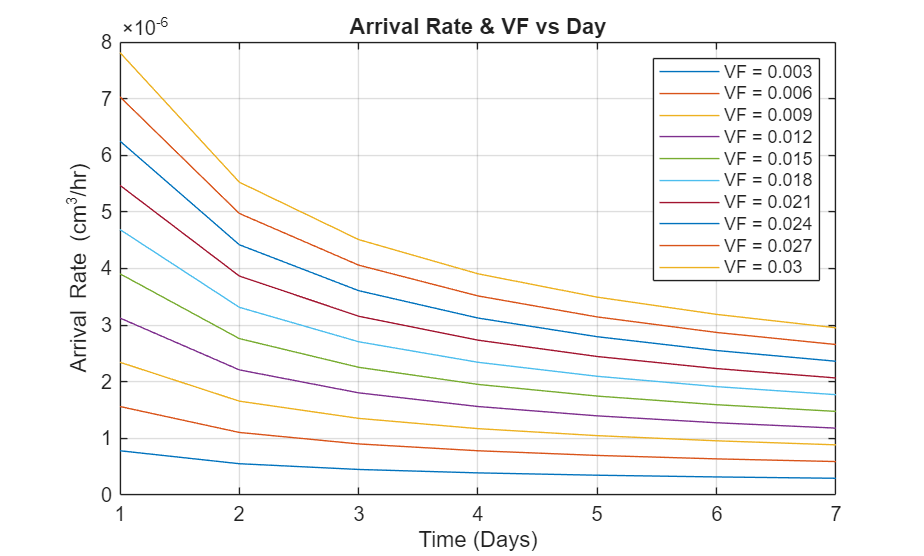

figure('Name','Arrival Rate & VF')
plot(time,ra(1,:))
hold on
grid on
plot(time,ra(2,:))
plot(time,ra(3,:))
plot(time,ra(4,:))
plot(time,ra(5,:))
plot(time,ra(6,:))
plot(time,ra(7,:))
plot(time,ra(8,:))
plot(time,ra(9,:))
plot(time,ra(10,:))
legend('VF = 0.003', 'VF = 0.006', 'VF = 0.009', 'VF = 0.012', ...
    'VF = 0.015', 'VF = 0.018', 'VF = 0.021', 'VF = 0.024', ...
    'VF = 0.027', 'VF = 0.03')
xlabel('Time (Days)')
ylabel('Arrival Rate (cm^3/hr)')
title('Arrival Rate & VF vs Day')

# Question 10)

Report the 7th day arrival rate value for VF of 0.03.  Give the result in units of mm^3/hr to four decimal places. 

disp(num2str(ra(10,7)*1000));

0.0029528


# Question 11)

Recently, there has been increasing interest in using deployable  sails to deorbit satellites in low orbits at the end of their useful  lifetimes. This increases their rate of orbit decay and removes the  spacecraft from active orbits faster than natural decay. Assume k =  1.38e-23 J/K, g = 9.81 m/s2, R = 8.314 J/(mol*K, mass density =  1.2023e-13 kg/m3, scale height = 124 km. if you need any of these  values. 

Part a) Calculate the time taken to naturally de-orbit (with no sail) a 1 kg satellite with frontal area 100 cm2(CubeSat idea) from an initial operational circular orbit at 800 km. Use a  snapshot of the orbital lifetime (display the time in days to the  nearest day).  

## Vars

k = 1.38e-23; %J/K
g = 9.81;
R = 8.314; %J/mol*K
rho = 1.2023e-13; %kg/m3
Cd = 2.2; %indus. standard assumption
h = 124*1000; %meters
m = 1; %kg
A = 0.01; %m^2
r = (6378 + 800)*1000; %meters
mu = 3.986e+14; %m^3/s^2

## EQs

dadt = -rho*((Cd*A)/m)*(mu*r)^0.5;
lt = -h/dadt;
lt_days = lt/(24*3600);

disp(num2str(lt_days));

10143.8318


# Question 12

Recently, there has been increasing interest in using deployable  sails to deorbit satellites in low orbits at the end of their useful  lifetimes. Assume k = 1.38e-23 J/K, g = 9.81 m/s2, R = 8.314 J/(mol*K,  mass density = 1.2023e-13 kg/m3, scale height = 124 km. if you need any  of these values. 

part b) Plot the time taken to de-orbit (from the same initial orbit) if the spacecraft deployed a drag sail with frontal sizes from 0.01 m2 (basically no sail) to 1m2 .  Please display the time in days.  

A = linspace(0.01,1,100);
dadt2 = -rho*((Cd.*A)./m)*(mu*r)^0.5;
lt2 = -h./dadt2;
lt_days2 = lt2/(24*3600);

## Plotting

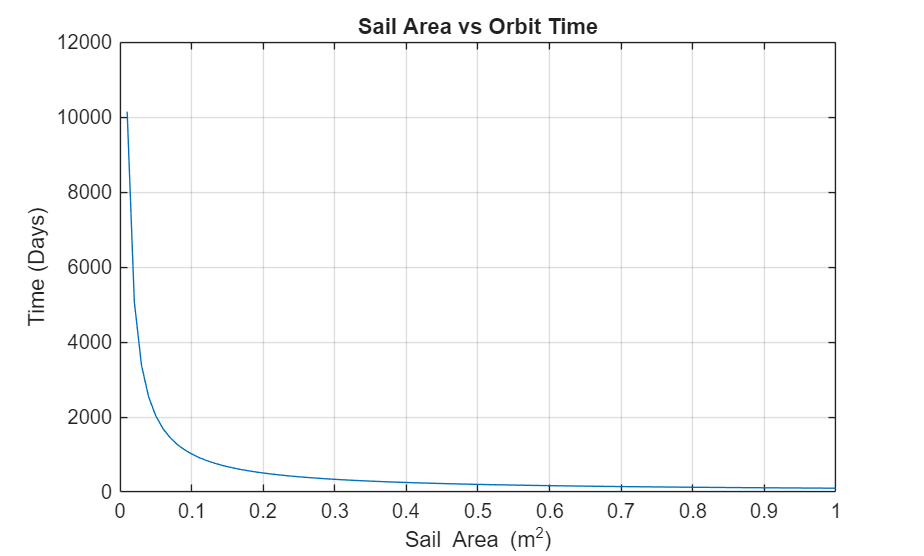

figure('Name','Sail Area vs Orbit Time')
plot(A,lt_days2)
grid on
xlabel('Sail Area (m^2)')
ylabel('Time (Days)')
title('Sail Area vs Orbit Time')

# Question 13)

Problem 6 Recently, there has been increasing  interest in using deployable sails to deorbit satellites in low orbits  at the end of their useful lifetimes. This increases their rate of orbit decay and removes the spacecraft from active orbits faster than natural decay. Assume k = 1.38e-23 J/K, g = 9.81 m/s2, R = 8.314 J/(mol*K, mass density = 1.2023e-13 kg/m3, scale height = 124 km if you need any of  these values. 

part c) Report  the lifetime result for a 1 m2 solar sail in days to the nearest day

disp(num2str(lt_days2(end)));

101.4383


# Question 15)

Problem 7

When its apogee kick motor fails, a satellite intended for a geo-synchronous orbit is stranded in LEO in a 320 km circular orbit. The silver array  interconnects are now exposed to an unexpected higher fluence of atomic  oxygen that will erode them badly.

Part a) Plot the erosion depth (cm) due to atomic oxygen over time (per day  for a year) for solar minimum, solar maximum and solar average  conditions, assuming the solar arrays are always facing the ram  direction. Use the AO density table provided.  The table gives altitude  in km, number density for AO [1/m3] for solar min and solar max. 

## Vars

AOD = readmatrix("AODensity.txt");
rhomax = AOD(7,3)/1000000; %convrt to cm^3
rhomin = AOD(7,2)/1000000;
E = 10.5e-24; %cm^3/atom
mu = 398600; %km^3/s^2
r = 6378 + 320; %km
seconds = linspace(0,365.25*86400,500);

## EQs

V = (sqrt(mu/r))*10^5; %cm/s
dvdtmax = E*rhomax*V;
dvdtmin = E*rhomin*V; %units of time in seconds!
maxE = dvdtmax.*seconds;
minE = dvdtmin.*seconds;

## Plotting

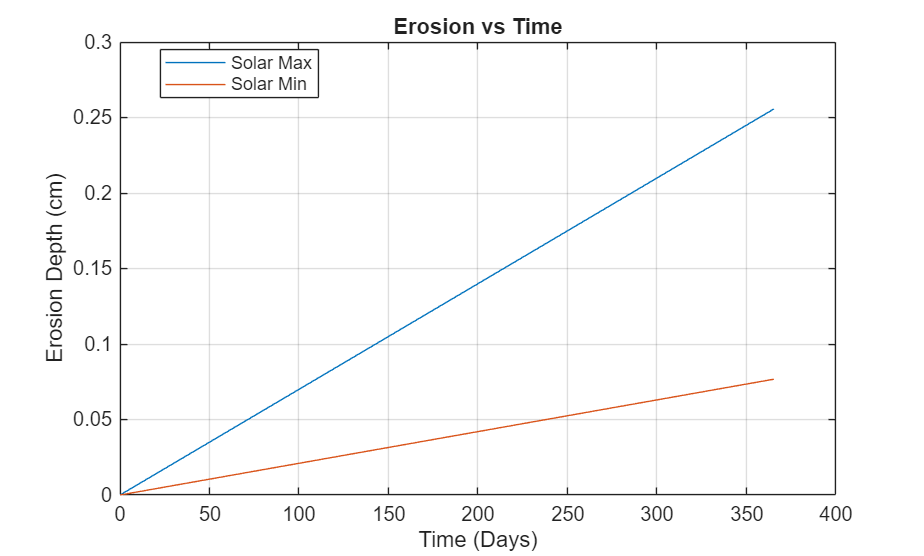

figure('Name','Erosion vs Time')
plot(seconds./86400,maxE)
hold on
grid on
plot(seconds./86400,minE)
xlabel('Time (Days)')
ylabel('Erosion Depth (cm)')
legend('Solar Max', 'Solar Min', Location='best')
title('Erosion vs Time')

# Question 16)       

Problem 7

part b) What is the erosion depth in cm to two decimal places at 1 year for solar max.

disp(num2str(maxE(end)));

0.25562


# Question 17)

Problem 7: 

Part c) If the silver interconnects are circular with a diameter of 0.04 cm, how much time does the company have to launch a rescue mission to  install a new kick motor before atomic oxygen creates mission failure?  Report the values in days to one day at solar max.       

[value, pos] = min(abs(maxE - 0.04)); %find the value closest to 0.04
disp(num2str(seconds(pos)/86400));

57.0932
